# GP-UKF static ver. (GP-UKFとUKFを同時に回してcompareする)

sat-obs-Sun position is fixed and satPos is origin.

軌道運動はとりあえず考えない

GPUKFの入力にmApp_pastMean を追加

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得
addpath(strcat(curdir, '/../../gpryui/'));

% create directory
% mkdir ../results/GPUKF_staticFixed/

tStart = tic;

### constants

% inputGP = "attitude"
% inputGP = "attitude, mApp_pastMean" % "attitude, mApp_pastMean" or "attitude, position, mApp_pastMean" or "attitude, relativePosition, mApp_pastMean"
% inputGP = "attitude, position, mApp_pastMean"
inputGP = "attitude, relativePosition, mApp_pastMean"

inputGP = "attitude, relativePosition, mApp_pastMean"



earthVSOP = vsopConst; % VSOP parameters
const = orbitConst; % constants for orbital motion

### simulation conditions

model = "boxWing"; % flatPlate or boxWing
trainMethod = "_lcAtti_onOrbit";

observation = 'mag'; % light curve magnitude or its inverse value

tSpanPast = 20;


% random number generator
rng(2022, 'twister');

### load true value and set noise

onjName_lcAtti_static.mat = ['t_', 'mApp', 'q', 'phi', 'theta', 'psi', 'w', 'sat', 'satPos', 'obsPos', 'sunPos']

% load true value
fName = strcat(model, trainMethod, ".mat")

fName = "boxWing_lcAtti_onOrbit.mat"

trueData = load(fName); % [t_, mApp, q, phi, theta, psi, w, sat, r, v, obsECI, sunPosI, jdHistory]

r_true_max = max(trueData.r, [], "all");
obsECI_true_max = max(trueData.obsECI, [], "all");
obsToTarget_max = max(trueData.r - trueData.obsECI, [], "all");


sat_true = trueData.sat; % 真値の表面特性
sat_u = trueData.sat; 
% UKFに用いる表面特性 
sat_u.Ca = 0.0;
sat_u.Cd = 0.5; % AS model の rho
sat_u.Cs = 1.0 - (sat_u.Ca + sat_u.Cs);
% sat_u.Cs = 0.5;

t_ = trueData.t_;
tn_ = size(t_, 1);

% set noise
sigTrue = 0.05;
% sigTrue = 0.1; % standard deviation of observation noise
Rtrue = sigTrue^2; % observation noise variance for relative magnitude

### UKF parameters

わからん

n_ = 3; % # of state variable := [error GRP] or [error GRP and angular rate]

% UKF Parameters
ukfPara.alp = 1e-4;
ukfPara.beta = 2;
ukfPara.kap = 3 - n_;% わからん
ukfPara.lam = ukfPara.alp^2 * (n_ + ukfPara.kap) - n_;
ukfPara.lam = 0; % わからん：上書きしてね？

ukfPara.w0m = ukfPara.lam / (n_ + ukfPara.lam); % for mean
ukfPara.wim = 1 / (2 * (n_ + ukfPara.lam));
ukfPara.w0c = ukfPara.lam / (n_ + ukfPara.lam) + (1 - ukfPara.alp^2 + ukfPara.beta); % for covariance
ukfPara.wic = ukfPara.wim;

ukfPara.w0m + 2*3*ukfPara.wim

ans = 1

ukfPara.w0c + 2*3*ukfPara.wic

ans = 4.0000


% estimated obsevation noise (standard deviation)
if strcmp(observation, 'mag')
    sigEst = 3 * sigTrue;
    Rest = sigEst.^2; % measurement noise
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
else
    sigEst = 1e-8;
    Rest = sigEst.^2;
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
end

### pre-allocation

% for GP-UKF
xEst_gu = zeros(tn_, n_); % := [error GRP]
Pdiag_gu = zeros(tn_, n_); % diagonal components of covariance matrix (Pcov)
qGlobal_gu = zeros(tn_, 4);
wGlobal_gu = zeros(tn_, 3);
mApp_pastMean = zeros(tn_, 1);
% for UKF
xEst_u = zeros(tn_, n_); % := [error GRP]
Pdiag_u = zeros(tn_, n_); % diagonal components of covariance matrix (Pcov)
qGlobal_u = zeros(tn_, 4);
wGlobal_u = zeros(tn_, 3);


ye_gu = zeros(tn_, 1); % GPUKFの予測値
ye_lc_gpAtti = zeros(tn_, 1); % GPUKFの姿勢に対してlc modelを用いた予測値 (for GP modelの精度確認)
ye_u = zeros(tn_, 1); % UKfの予測値

ye0 = 0; % わからん→sigma pointの中心？
yez = zeros(2*n_, 1);
yeOut = zeros(tn_, 1);

% observations
mAppNoise = trueData.mApp + sigTrue .* randn(tn_, 1); % true obs. (relative magnitude), gaussian distribution
obsRel = trueData.obsECI - trueData.r;
dTmp = vecnorm(obsRel, 2, 2); % [m], distance between sat and observer
mAppInv = magInv(mAppNoise(:,1), dTmp); % true obs. (relative magnitude inverse)

### initial estimate

% initial estimate
qGlobal_gu(1,:) = trueData.q(1,:); % true initial
qGlobal_u(1,:) = trueData.q(1,:); % true initial
% wGlobal_gu(1,:) = trueData.w(1,:); % true initial
mApp_pastMean(1,1) = trueData.mApp(1,1); % とりあえず真値の初期値をmApp_pastMeanの初期推定値として使う

% large initial error 
iniErr = deg2rad(90);
% qGlobal(1,:) = qMult(4, 1, zyx2q(4, iniErr, iniErr, iniErr), q(1,:));

% small initial error
iniErr_q = deg2rad([-10, 5, -10]); % zyx表記
% iniErr_w = deg2rad([1, 1, 1]); % [rad/s]

qGlobal_gu(1,:) = qMult(4, 1, zyx2q(4, iniErr_q(1,1), iniErr_q(1,2), iniErr_q(1,3)), trueData.q(1,:));
qGlobal_u(1,:) = qMult(4, 1, zyx2q(4, iniErr_q(1,1), iniErr_q(1,2), iniErr_q(1,3)), trueData.q(1,:));
% wGlobal(1,:) = wGlobal(1,:) + [iniErr_w(1), iniErr_w(2), iniErr_w(3)];

#### initial covariance for 3$\sigma
$ bound

Pdiag_gu(1,:) = (iniErr ./ 3).^2 .* ones(1, 3);
% Pdiag_gu(1,:) = (iniErr_q ./ 3).^2;
Pdiag_u(1,:) = (iniErr ./ 3).^2 .* ones(1, 3);
% p(1,:) = ([iniErr_q, iniErr_w] ./ 3).^2;
Pcov_gu = diag(Pdiag_gu(1,:));
Pcov_u = diag(Pdiag_u(1,:));

% x:= [error GRP, angular rate]
xEst_gu(1,:) = zeros(1, n_); % わからん→誤差GRPは毎回0にする．？
xEst_u(1,:) = zeros(1, n_);

#### initial obsevation step

load('constGP.mat'); % [x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do, params]
if strcmp(inputGP, "attitude, position, mApp_pastMean") % こっちの入力おかしいかも
    [ye_gu(1,1), ~] = gprNormal([qGlobal_gu(1,:), trueData.r(1,:)./r_true_max, trueData.obsECI(1,:)./obsECI_true_max, mApp_pastMean(1,1)], x_train, y_train, params, Kinv_Do); 
elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
    [ye_gu(1,1), ~] = gprNormal([qGlobal_gu(1,:), (trueData.r(1,:)-trueData.obsECI(1,:))./obsToTarget_max, mApp_pastMean(1,1)], x_train, y_train, params, Kinv_Do);
elseif strcmp(inputGP, "attitude, mApp_pastMean")
    [ye_gu(1,1), ~] = gprNormal([qGlobal_gu(1,:),mApp_pastMean(1,1)], x_train, y_train, params, Kinv_Do);
elseif strcmp(inputGP, "attitude")
    [ye_gu(1,1), ~] = gprNormal([qGlobal_gu(1,:)], x_train, y_train, params, Kinv_Do);
end    
ye_gu(1,1) = ye_gu(1,1) + y_train_mean(1,1);

nu = 1; % sunlit?, earth shadowing?
ye_lc_gpAtti(1,1) = lc(sat_true, 4, qGlobal_gu(1,:), trueData.r(1,:), trueData.obsECI(1,:), trueData.sunPosI(1,:), nu, 'AS'); % 初期予測観測値

ye_u(1,1) = lc(sat_u, 4, qGlobal_u(1,:), trueData.r(1,:), trueData.obsECI(1,:), trueData.sunPosI(1,:), nu, 'AS');

### Generalized Rodrigues parameters

aGRP = 1;
fGRP = 2 * (aGRP + 1);

### GP-UKF

% load('constGP.mat'); % [x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do, params]
% filter = "GPUKF" % "GPUKF" or "UKF"


for i = 1:tn_-1
    ti_GPUKF = tic;
    
    dt_ = t_(i+1) - t_(i);
    [qGlobal_gu(i+1, :), wGlobal_gu(i+1, :), Pcov_gu, Pdiag_gu(i+1,:), qGlobal_u(i+1,:), wGlobal_u(i+1,:), Pcov_u, Pdiag_u(i+1,:), ye_gu(i+1,1), ye_lc_gpAtti(i+1,1), ye_u(i+1,1), mApp_pastMean(i+1)] = lcGPUKF_cmp_staticPastMean_onOrbit(dt_, xEst_gu(i, :), xEst_u(i,:), Pcov_gu, Pcov_u, mAppNoise(i), mAppNoise(i+1), ye_gu(i), ...
        ukfPara, Qest, Rest, fGRP, aGRP, qGlobal_gu(i, :), qGlobal_u(i,:), trueData.w(i,:), trueData.r(i+1,:), trueData.obsECI(i+1,:), trueData.sunPosI(i+1,:), mApp_pastMean(i,1), sat_true, sat_u, const, earthVSOP, x_train, y_train, y_train_mean, params, Kinv_Dp, Kinv_Do, trueData.jdHistory(i), tSpanPast, inputGP, r_true_max, obsECI_true_max, obsToTarget_max);

    fprintf("the number of the time step i: %d \n", i);
    fprintf("the calculation time to go forward to the next step: %f [min] \n", toc(ti_GPUKF)/60);
    % [qGlobal(i+1, :), wGlobal(i+1, :), Pcov] = lcGPUKF_staticFixed(dt_, xEst(i, :), Pcov, mAppNoise(i+1), ...
    %     ukfPara, Qest, Rest, fGRP, aGRP, qGlobal(i, :), wGlobal(i,:), trueData.satPos(i+1,:), trueData.obsPos(i+1,:), trueData.sunPos(i+1,:), trueData.sat, const, earthVSOP, x_train, y_train, y_train_mean, params, Kinv_Dp, Kinv_Do);
end

the number of the time step i: 1 


the calculation time to go forward to the next step: 9.878378 [min] 


the number of the time step i: 2 


the calculation time to go forward to the next step: 11.413876 [min] 


the number of the time step i: 3 


the calculation time to go forward to the next step: 10.355060 [min] 


the number of the time step i: 4 


the calculation time to go forward to the next step: 10.275875 [min] 


the number of the time step i: 5 


the calculation time to go forward to the next step: 10.725492 [min] 


the number of the time step i: 6 


the calculation time to go forward to the next step: 11.050249 [min] 


the number of the time step i: 7 


the calculation time to go forward to the next step: 10.415158 [min] 


the number of the time step i: 8 


the calculation time to go forward to the next step: 10.343843 [min] 


the number of the time step i: 9 


the calculation time to go forward to the next step: 10.211636 [min] 


the number of the time step i: 10 


the calculation time to go forward to the next step: 11.475264 [min] 


the number of the time step i: 11 


the calculation time to go forward to the next step: 10.853066 [min] 


the number of the time step i: 12 


the calculation time to go forward to the next step: 10.368206 [min] 


the number of the time step i: 13 


the calculation time to go forward to the next step: 10.373872 [min] 


the number of the time step i: 14 


the calculation time to go forward to the next step: 10.998228 [min] 


the number of the time step i: 15 


the calculation time to go forward to the next step: 11.012177 [min] 


the number of the time step i: 16 


the calculation time to go forward to the next step: 10.082904 [min] 


the number of the time step i: 17 


the calculation time to go forward to the next step: 10.299427 [min] 


the number of the time step i: 18 


the calculation time to go forward to the next step: 10.912241 [min] 


the number of the time step i: 19 


the calculation time to go forward to the next step: 11.062990 [min] 


the number of the time step i: 20 


the calculation time to go forward to the next step: 10.385056 [min] 


the number of the time step i: 21 


the calculation time to go forward to the next step: 10.337852 [min] 


the number of the time step i: 22 


the calculation time to go forward to the next step: 10.954691 [min] 


the number of the time step i: 23 


the calculation time to go forward to the next step: 10.632193 [min] 


the number of the time step i: 24 


the calculation time to go forward to the next step: 9.986587 [min] 


the number of the time step i: 25 


the calculation time to go forward to the next step: 9.835437 [min] 


the number of the time step i: 26 


the calculation time to go forward to the next step: 11.415048 [min] 


the number of the time step i: 27 


the calculation time to go forward to the next step: 10.263874 [min] 


the number of the time step i: 28 


the calculation time to go forward to the next step: 10.203087 [min] 


the number of the time step i: 29 


the calculation time to go forward to the next step: 10.179526 [min] 


the number of the time step i: 30 


the calculation time to go forward to the next step: 11.012004 [min] 


the number of the time step i: 31 


the calculation time to go forward to the next step: 10.881870 [min] 


the number of the time step i: 32 


the calculation time to go forward to the next step: 9.753955 [min] 


the number of the time step i: 33 


the calculation time to go forward to the next step: 10.377855 [min] 


the number of the time step i: 34 


the calculation time to go forward to the next step: 11.318553 [min] 


the number of the time step i: 35 


the calculation time to go forward to the next step: 10.055523 [min] 


the number of the time step i: 36 


the calculation time to go forward to the next step: 10.168451 [min] 


the number of the time step i: 37 


the calculation time to go forward to the next step: 10.731984 [min] 


the number of the time step i: 38 


the calculation time to go forward to the next step: 10.672164 [min] 


the number of the time step i: 39 


the calculation time to go forward to the next step: 10.139941 [min] 


the number of the time step i: 40 


the calculation time to go forward to the next step: 9.912078 [min] 


the number of the time step i: 41 


the calculation time to go forward to the next step: 10.793359 [min] 


the number of the time step i: 42 


the calculation time to go forward to the next step: 10.569192 [min] 


the number of the time step i: 43 


the calculation time to go forward to the next step: 10.005298 [min] 


the number of the time step i: 44 


the calculation time to go forward to the next step: 10.269161 [min] 


the number of the time step i: 45 


the calculation time to go forward to the next step: 10.489264 [min] 


the number of the time step i: 46 


the calculation time to go forward to the next step: 11.679931 [min] 


the number of the time step i: 47 


the calculation time to go forward to the next step: 10.297853 [min] 


the number of the time step i: 48 


the calculation time to go forward to the next step: 10.318533 [min] 


the number of the time step i: 49 


the calculation time to go forward to the next step: 10.734834 [min] 


the number of the time step i: 50 


the calculation time to go forward to the next step: 10.955955 [min] 


the number of the time step i: 51 


the calculation time to go forward to the next step: 10.189845 [min] 


the number of the time step i: 52 


the calculation time to go forward to the next step: 10.229191 [min] 


the number of the time step i: 53 


the calculation time to go forward to the next step: 10.770367 [min] 


the number of the time step i: 54 


the calculation time to go forward to the next step: 10.972352 [min] 


the number of the time step i: 55 


the calculation time to go forward to the next step: 10.114787 [min] 


the number of the time step i: 56 


the calculation time to go forward to the next step: 9.848785 [min] 


the number of the time step i: 57 


the calculation time to go forward to the next step: 11.050840 [min] 


the number of the time step i: 58 


the calculation time to go forward to the next step: 10.585378 [min] 


the number of the time step i: 59 


the calculation time to go forward to the next step: 10.250568 [min] 


the number of the time step i: 60 


the calculation time to go forward to the next step: 10.017186 [min] 


the number of the time step i: 61 


the calculation time to go forward to the next step: 11.110095 [min] 


the number of the time step i: 62 


the calculation time to go forward to the next step: 10.470772 [min] 


the number of the time step i: 63 


the calculation time to go forward to the next step: 10.387386 [min] 


the number of the time step i: 64 


the calculation time to go forward to the next step: 10.372819 [min] 


the number of the time step i: 65 


the calculation time to go forward to the next step: 11.178724 [min] 


the number of the time step i: 66 


the calculation time to go forward to the next step: 10.107817 [min] 


the number of the time step i: 67 


the calculation time to go forward to the next step: 10.427626 [min] 


the number of the time step i: 68 


the calculation time to go forward to the next step: 10.441433 [min] 


the number of the time step i: 69 


the calculation time to go forward to the next step: 10.919603 [min] 


the number of the time step i: 70 


the calculation time to go forward to the next step: 10.424818 [min] 


the number of the time step i: 71 


the calculation time to go forward to the next step: 10.217031 [min] 


the number of the time step i: 72 


the calculation time to go forward to the next step: 12.538449 [min] 


the number of the time step i: 73 


the calculation time to go forward to the next step: 11.547089 [min] 


the number of the time step i: 74 


the calculation time to go forward to the next step: 10.018439 [min] 


the number of the time step i: 75 


the calculation time to go forward to the next step: 9.966091 [min] 


the number of the time step i: 76 


the calculation time to go forward to the next step: 11.707784 [min] 


the number of the time step i: 77 


the calculation time to go forward to the next step: 10.751024 [min] 


the number of the time step i: 78 


the calculation time to go forward to the next step: 10.474176 [min] 


the number of the time step i: 79 


the calculation time to go forward to the next step: 10.047134 [min] 


the number of the time step i: 80 


the calculation time to go forward to the next step: 11.301889 [min] 


the number of the time step i: 81 


the calculation time to go forward to the next step: 10.277488 [min] 


the number of the time step i: 82 


the calculation time to go forward to the next step: 10.558800 [min] 


the number of the time step i: 83 


the calculation time to go forward to the next step: 10.402597 [min] 


the number of the time step i: 84 


the calculation time to go forward to the next step: 11.270170 [min] 


the number of the time step i: 85 


the calculation time to go forward to the next step: 10.689937 [min] 


the number of the time step i: 86 


the calculation time to go forward to the next step: 10.277379 [min] 


the number of the time step i: 87 


the calculation time to go forward to the next step: 10.369913 [min] 


the number of the time step i: 88 


the calculation time to go forward to the next step: 11.726176 [min] 


the number of the time step i: 89 


the calculation time to go forward to the next step: 11.030454 [min] 


the number of the time step i: 90 


the calculation time to go forward to the next step: 10.239324 [min] 


the number of the time step i: 91 


the calculation time to go forward to the next step: 11.293706 [min] 


the number of the time step i: 92 


the calculation time to go forward to the next step: 11.115168 [min] 


the number of the time step i: 93 


the calculation time to go forward to the next step: 10.211619 [min] 


the number of the time step i: 94 


the calculation time to go forward to the next step: 10.304758 [min] 


the number of the time step i: 95 


the calculation time to go forward to the next step: 11.115503 [min] 


the number of the time step i: 96 


the calculation time to go forward to the next step: 10.678805 [min] 


the number of the time step i: 97 


the calculation time to go forward to the next step: 10.884204 [min] 


the number of the time step i: 98 


the calculation time to go forward to the next step: 10.359848 [min] 


the number of the time step i: 99 


the calculation time to go forward to the next step: 10.816769 [min] 


the number of the time step i: 100 


the calculation time to go forward to the next step: 10.802606 [min] 


the number of the time step i: 101 


the calculation time to go forward to the next step: 10.503902 [min] 


the number of the time step i: 102 


the calculation time to go forward to the next step: 10.278275 [min] 


the number of the time step i: 103 


the calculation time to go forward to the next step: 11.096861 [min] 


the number of the time step i: 104 


the calculation time to go forward to the next step: 11.044163 [min] 


the number of the time step i: 105 


the calculation time to go forward to the next step: 10.082743 [min] 


the number of the time step i: 106 


the calculation time to go forward to the next step: 10.867430 [min] 


the number of the time step i: 107 


the calculation time to go forward to the next step: 10.834856 [min] 


the number of the time step i: 108 


the calculation time to go forward to the next step: 10.478872 [min] 


the number of the time step i: 109 


the calculation time to go forward to the next step: 10.323528 [min] 


the number of the time step i: 110 


the calculation time to go forward to the next step: 10.870324 [min] 


the number of the time step i: 111 


the calculation time to go forward to the next step: 11.079670 [min] 


the number of the time step i: 112 


the calculation time to go forward to the next step: 9.856768 [min] 


the number of the time step i: 113 


the calculation time to go forward to the next step: 10.480046 [min] 


the number of the time step i: 114 


the calculation time to go forward to the next step: 11.281655 [min] 


the number of the time step i: 115 


the calculation time to go forward to the next step: 10.839489 [min] 


the number of the time step i: 116 


the calculation time to go forward to the next step: 10.362424 [min] 


the number of the time step i: 117 


the calculation time to go forward to the next step: 10.151674 [min] 


the number of the time step i: 118 


the calculation time to go forward to the next step: 11.442046 [min] 


the number of the time step i: 119 


the calculation time to go forward to the next step: 10.847520 [min] 


the number of the time step i: 120 


the calculation time to go forward to the next step: 10.388359 [min] 


the number of the time step i: 121 


the calculation time to go forward to the next step: 10.873584 [min] 


the number of the time step i: 122 


the calculation time to go forward to the next step: 10.931646 [min] 


the number of the time step i: 123 


the calculation time to go forward to the next step: 10.483549 [min] 


the number of the time step i: 124 


the calculation time to go forward to the next step: 10.003185 [min] 


the number of the time step i: 125 


the calculation time to go forward to the next step: 10.812420 [min] 


the number of the time step i: 126 


the calculation time to go forward to the next step: 11.163710 [min] 


the number of the time step i: 127 


the calculation time to go forward to the next step: 10.245360 [min] 


the number of the time step i: 128 


the calculation time to go forward to the next step: 10.092452 [min] 


the number of the time step i: 129 


the calculation time to go forward to the next step: 11.154484 [min] 


the number of the time step i: 130 


the calculation time to go forward to the next step: 11.467813 [min] 


the number of the time step i: 131 


the calculation time to go forward to the next step: 10.630380 [min] 


the number of the time step i: 132 


the calculation time to go forward to the next step: 10.256276 [min] 


the number of the time step i: 133 


the calculation time to go forward to the next step: 10.478919 [min] 


the number of the time step i: 134 


the calculation time to go forward to the next step: 11.063825 [min] 


the number of the time step i: 135 


the calculation time to go forward to the next step: 10.677696 [min] 


the number of the time step i: 136 


the calculation time to go forward to the next step: 10.521706 [min] 


the number of the time step i: 137 


the calculation time to go forward to the next step: 10.655386 [min] 


the number of the time step i: 138 


the calculation time to go forward to the next step: 11.314714 [min] 


the number of the time step i: 139 


the calculation time to go forward to the next step: 10.608793 [min] 


the number of the time step i: 140 


the calculation time to go forward to the next step: 10.625684 [min] 


the number of the time step i: 141 


the calculation time to go forward to the next step: 10.031048 [min] 


the number of the time step i: 142 


the calculation time to go forward to the next step: 11.498863 [min] 


the number of the time step i: 143 


the calculation time to go forward to the next step: 10.416812 [min] 


the number of the time step i: 144 


the calculation time to go forward to the next step: 10.308664 [min] 


the number of the time step i: 145 


the calculation time to go forward to the next step: 9.891119 [min] 


the number of the time step i: 146 


the calculation time to go forward to the next step: 10.929948 [min] 


the number of the time step i: 147 


the calculation time to go forward to the next step: 10.738796 [min] 


the number of the time step i: 148 


the calculation time to go forward to the next step: 9.743124 [min] 


the number of the time step i: 149 


the calculation time to go forward to the next step: 9.897482 [min] 


the number of the time step i: 150 


the calculation time to go forward to the next step: 11.100986 [min] 


the number of the time step i: 151 


the calculation time to go forward to the next step: 10.581224 [min] 


the number of the time step i: 152 


the calculation time to go forward to the next step: 10.053686 [min] 


the number of the time step i: 153 


the calculation time to go forward to the next step: 10.448709 [min] 


the number of the time step i: 154 


the calculation time to go forward to the next step: 11.323812 [min] 


the number of the time step i: 155 


the calculation time to go forward to the next step: 10.799188 [min] 


the number of the time step i: 156 


the calculation time to go forward to the next step: 9.780570 [min] 


the number of the time step i: 157 


the calculation time to go forward to the next step: 10.341340 [min] 


the number of the time step i: 158 


the calculation time to go forward to the next step: 10.767055 [min] 


the number of the time step i: 159 


the calculation time to go forward to the next step: 10.118723 [min] 


the number of the time step i: 160 


the calculation time to go forward to the next step: 10.038626 [min] 


the number of the time step i: 161 


the calculation time to go forward to the next step: 10.449490 [min] 


the number of the time step i: 162 


the calculation time to go forward to the next step: 10.872842 [min] 


the number of the time step i: 163 


the calculation time to go forward to the next step: 9.767897 [min] 


the number of the time step i: 164 


the calculation time to go forward to the next step: 10.095151 [min] 


the number of the time step i: 165 


the calculation time to go forward to the next step: 10.757509 [min] 


the number of the time step i: 166 


the calculation time to go forward to the next step: 10.603245 [min] 


the number of the time step i: 167 


the calculation time to go forward to the next step: 10.145332 [min] 


the number of the time step i: 168 


the calculation time to go forward to the next step: 9.945551 [min] 


the number of the time step i: 169 


the calculation time to go forward to the next step: 11.180141 [min] 


the number of the time step i: 170 


the calculation time to go forward to the next step: 10.431952 [min] 


the number of the time step i: 171 


the calculation time to go forward to the next step: 9.996030 [min] 


the number of the time step i: 172 


the calculation time to go forward to the next step: 10.226417 [min] 


the number of the time step i: 173 


the calculation time to go forward to the next step: 10.704069 [min] 


the number of the time step i: 174 


the calculation time to go forward to the next step: 10.481568 [min] 


the number of the time step i: 175 


the calculation time to go forward to the next step: 9.826790 [min] 


the number of the time step i: 176 


the calculation time to go forward to the next step: 10.301791 [min] 


the number of the time step i: 177 


the calculation time to go forward to the next step: 10.770011 [min] 


the number of the time step i: 178 


the calculation time to go forward to the next step: 10.537465 [min] 


the number of the time step i: 179 


the calculation time to go forward to the next step: 9.910514 [min] 


the number of the time step i: 180 


the calculation time to go forward to the next step: 10.334445 [min] 


the number of the time step i: 181 


the calculation time to go forward to the next step: 10.601644 [min] 


the number of the time step i: 182 


the calculation time to go forward to the next step: 10.841001 [min] 


the number of the time step i: 183 


the calculation time to go forward to the next step: 10.077741 [min] 


the number of the time step i: 184 


the calculation time to go forward to the next step: 10.056431 [min] 


the number of the time step i: 185 


the calculation time to go forward to the next step: 10.993296 [min] 


the number of the time step i: 186 


the calculation time to go forward to the next step: 10.136896 [min] 


the number of the time step i: 187 


the calculation time to go forward to the next step: 10.066421 [min] 


the number of the time step i: 188 


the calculation time to go forward to the next step: 10.153773 [min] 


the number of the time step i: 189 


the calculation time to go forward to the next step: 10.716220 [min] 


the number of the time step i: 190 


the calculation time to go forward to the next step: 10.084087 [min] 


the number of the time step i: 191 


the calculation time to go forward to the next step: 10.264280 [min] 


the number of the time step i: 192 


the calculation time to go forward to the next step: 10.235331 [min] 


the number of the time step i: 193 


the calculation time to go forward to the next step: 10.493262 [min] 


the number of the time step i: 194 


the calculation time to go forward to the next step: 10.221658 [min] 


the number of the time step i: 195 


the calculation time to go forward to the next step: 10.073598 [min] 


the number of the time step i: 196 


the calculation time to go forward to the next step: 10.375363 [min] 


the number of the time step i: 197 


the calculation time to go forward to the next step: 10.861958 [min] 


the number of the time step i: 198 


the calculation time to go forward to the next step: 9.764906 [min] 


the number of the time step i: 199 


the calculation time to go forward to the next step: 10.299265 [min] 


the number of the time step i: 200 


the calculation time to go forward to the next step: 10.320161 [min] 


the number of the time step i: 201 


the calculation time to go forward to the next step: 10.758516 [min] 


the number of the time step i: 202 


the calculation time to go forward to the next step: 9.572556 [min] 


the number of the time step i: 203 


the calculation time to go forward to the next step: 10.337861 [min] 


the number of the time step i: 204 


the calculation time to go forward to the next step: 10.445420 [min] 


the number of the time step i: 205 


the calculation time to go forward to the next step: 10.532263 [min] 


the number of the time step i: 206 


the calculation time to go forward to the next step: 10.096535 [min] 


the number of the time step i: 207 


the calculation time to go forward to the next step: 10.124213 [min] 


the number of the time step i: 208 


the calculation time to go forward to the next step: 10.417521 [min] 


the number of the time step i: 209 


the calculation time to go forward to the next step: 10.852624 [min] 


the number of the time step i: 210 


the calculation time to go forward to the next step: 9.873050 [min] 


the number of the time step i: 211 


the calculation time to go forward to the next step: 10.894320 [min] 


the number of the time step i: 212 


the calculation time to go forward to the next step: 10.937015 [min] 


the number of the time step i: 213 


the calculation time to go forward to the next step: 10.577590 [min] 


the number of the time step i: 214 


the calculation time to go forward to the next step: 10.454861 [min] 


the number of the time step i: 215 


the calculation time to go forward to the next step: 10.613810 [min] 


the number of the time step i: 216 


the calculation time to go forward to the next step: 10.845246 [min] 


the number of the time step i: 217 


the calculation time to go forward to the next step: 10.737604 [min] 


the number of the time step i: 218 


the calculation time to go forward to the next step: 10.010590 [min] 


the number of the time step i: 219 


the calculation time to go forward to the next step: 10.100128 [min] 


the number of the time step i: 220 


the calculation time to go forward to the next step: 10.865335 [min] 


the number of the time step i: 221 


the calculation time to go forward to the next step: 10.628575 [min] 


the number of the time step i: 222 


the calculation time to go forward to the next step: 10.112946 [min] 


the number of the time step i: 223 


the calculation time to go forward to the next step: 11.026120 [min] 


the number of the time step i: 224 


the calculation time to go forward to the next step: 11.020509 [min] 


the number of the time step i: 225 


the calculation time to go forward to the next step: 10.247863 [min] 


the number of the time step i: 226 


the calculation time to go forward to the next step: 10.322233 [min] 


the number of the time step i: 227 


the calculation time to go forward to the next step: 10.661674 [min] 


the number of the time step i: 228 


the calculation time to go forward to the next step: 10.895502 [min] 


the number of the time step i: 229 


the calculation time to go forward to the next step: 10.546029 [min] 


the number of the time step i: 230 


the calculation time to go forward to the next step: 10.342781 [min] 


the number of the time step i: 231 


the calculation time to go forward to the next step: 11.609354 [min] 


the number of the time step i: 232 


the calculation time to go forward to the next step: 11.251964 [min] 


the number of the time step i: 233 


the calculation time to go forward to the next step: 10.168666 [min] 


the number of the time step i: 234 


the calculation time to go forward to the next step: 9.953741 [min] 


the number of the time step i: 235 


the calculation time to go forward to the next step: 11.559997 [min] 


the number of the time step i: 236 


the calculation time to go forward to the next step: 10.644913 [min] 


the number of the time step i: 237 


the calculation time to go forward to the next step: 10.165389 [min] 


the number of the time step i: 238 


the calculation time to go forward to the next step: 10.244254 [min] 


the number of the time step i: 239 


the calculation time to go forward to the next step: 11.162732 [min] 


the number of the time step i: 240 


the calculation time to go forward to the next step: 10.380056 [min] 


the number of the time step i: 241 


the calculation time to go forward to the next step: 10.109320 [min] 


the number of the time step i: 242 


the calculation time to go forward to the next step: 10.549966 [min] 


the number of the time step i: 243 


the calculation time to go forward to the next step: 11.368804 [min] 


the number of the time step i: 244 


the calculation time to go forward to the next step: 10.138387 [min] 


the number of the time step i: 245 


the calculation time to go forward to the next step: 10.514491 [min] 


the number of the time step i: 246 


the calculation time to go forward to the next step: 10.488234 [min] 


the number of the time step i: 247 


the calculation time to go forward to the next step: 10.936731 [min] 


the number of the time step i: 248 


the calculation time to go forward to the next step: 10.314034 [min] 


the number of the time step i: 249 


the calculation time to go forward to the next step: 10.129617 [min] 


the number of the time step i: 250 


the calculation time to go forward to the next step: 10.644444 [min] 


the number of the time step i: 251 


the calculation time to go forward to the next step: 10.753447 [min] 


the number of the time step i: 252 


the calculation time to go forward to the next step: 10.172152 [min] 


the number of the time step i: 253 


the calculation time to go forward to the next step: 10.052451 [min] 


the number of the time step i: 254 


the calculation time to go forward to the next step: 11.510888 [min] 


the number of the time step i: 255 


the calculation time to go forward to the next step: 10.352395 [min] 


the number of the time step i: 256 


the calculation time to go forward to the next step: 10.575319 [min] 


the number of the time step i: 257 


the calculation time to go forward to the next step: 10.328204 [min] 


the number of the time step i: 258 


the calculation time to go forward to the next step: 10.894579 [min] 


the number of the time step i: 259 


the calculation time to go forward to the next step: 10.569831 [min] 


the number of the time step i: 260 


the calculation time to go forward to the next step: 10.164661 [min] 


the number of the time step i: 261 


the calculation time to go forward to the next step: 10.202374 [min] 


the number of the time step i: 262 


the calculation time to go forward to the next step: 11.039157 [min] 


the number of the time step i: 263 


the calculation time to go forward to the next step: 10.830477 [min] 


the number of the time step i: 264 


the calculation time to go forward to the next step: 10.366705 [min] 


the number of the time step i: 265 


the calculation time to go forward to the next step: 10.016631 [min] 


the number of the time step i: 266 


the calculation time to go forward to the next step: 10.830870 [min] 


the number of the time step i: 267 


the calculation time to go forward to the next step: 10.944213 [min] 


the number of the time step i: 268 


the calculation time to go forward to the next step: 10.335901 [min] 


the number of the time step i: 269 


the calculation time to go forward to the next step: 9.969371 [min] 


the number of the time step i: 270 


the calculation time to go forward to the next step: 10.386948 [min] 


the number of the time step i: 271 


the calculation time to go forward to the next step: 11.142681 [min] 


the number of the time step i: 272 


the calculation time to go forward to the next step: 10.061938 [min] 


the number of the time step i: 273 


the calculation time to go forward to the next step: 10.574100 [min] 


the number of the time step i: 274 


the calculation time to go forward to the next step: 10.944657 [min] 


the number of the time step i: 275 


the calculation time to go forward to the next step: 10.415644 [min] 


the number of the time step i: 276 


the calculation time to go forward to the next step: 10.264838 [min] 


the number of the time step i: 277 


the calculation time to go forward to the next step: 10.230383 [min] 


the number of the time step i: 278 


the calculation time to go forward to the next step: 10.652995 [min] 


the number of the time step i: 279 


the calculation time to go forward to the next step: 10.717486 [min] 


the number of the time step i: 280 


the calculation time to go forward to the next step: 10.519702 [min] 


the number of the time step i: 281 


the calculation time to go forward to the next step: 9.979207 [min] 


the number of the time step i: 282 


the calculation time to go forward to the next step: 10.701216 [min] 


the number of the time step i: 283 


the calculation time to go forward to the next step: 10.721482 [min] 


the number of the time step i: 284 


the calculation time to go forward to the next step: 9.643152 [min] 


the number of the time step i: 285 


the calculation time to go forward to the next step: 10.123726 [min] 


the number of the time step i: 286 


the calculation time to go forward to the next step: 9.994782 [min] 


the number of the time step i: 287 


the calculation time to go forward to the next step: 10.359886 [min] 


the number of the time step i: 288 


the calculation time to go forward to the next step: 9.931871 [min] 


the number of the time step i: 289 


the calculation time to go forward to the next step: 10.114714 [min] 


the number of the time step i: 290 


the calculation time to go forward to the next step: 10.277302 [min] 


the number of the time step i: 291 


the calculation time to go forward to the next step: 10.821747 [min] 


the number of the time step i: 292 


the calculation time to go forward to the next step: 9.896108 [min] 


the number of the time step i: 293 


the calculation time to go forward to the next step: 9.828603 [min] 


the number of the time step i: 294 


the calculation time to go forward to the next step: 10.454527 [min] 


the number of the time step i: 295 


the calculation time to go forward to the next step: 10.754635 [min] 


the number of the time step i: 296 


the calculation time to go forward to the next step: 9.808762 [min] 


the number of the time step i: 297 


the calculation time to go forward to the next step: 10.006047 [min] 


the number of the time step i: 298 


the calculation time to go forward to the next step: 10.834626 [min] 


the number of the time step i: 299 


the calculation time to go forward to the next step: 10.193823 [min] 


the number of the time step i: 300 


the calculation time to go forward to the next step: 9.723247 [min] 


the number of the time step i: 301 


the calculation time to go forward to the next step: 9.745799 [min] 


the number of the time step i: 302 


the calculation time to go forward to the next step: 10.779789 [min] 


the number of the time step i: 303 


the calculation time to go forward to the next step: 10.338028 [min] 


the number of the time step i: 304 


the calculation time to go forward to the next step: 9.582415 [min] 


the number of the time step i: 305 


the calculation time to go forward to the next step: 10.451257 [min] 


the number of the time step i: 306 


the calculation time to go forward to the next step: 11.235029 [min] 


the number of the time step i: 307 


the calculation time to go forward to the next step: 10.720672 [min] 


the number of the time step i: 308 


the calculation time to go forward to the next step: 9.741918 [min] 


the number of the time step i: 309 


the calculation time to go forward to the next step: 10.389427 [min] 


the number of the time step i: 310 


the calculation time to go forward to the next step: 10.562684 [min] 


the number of the time step i: 311 


the calculation time to go forward to the next step: 10.011999 [min] 


the number of the time step i: 312 


the calculation time to go forward to the next step: 9.698901 [min] 


the number of the time step i: 313 


the calculation time to go forward to the next step: 10.560801 [min] 


the number of the time step i: 314 


the calculation time to go forward to the next step: 10.573500 [min] 


the number of the time step i: 315 


the calculation time to go forward to the next step: 9.776869 [min] 


the number of the time step i: 316 


the calculation time to go forward to the next step: 9.784297 [min] 


the number of the time step i: 317 


the calculation time to go forward to the next step: 10.355137 [min] 


the number of the time step i: 318 


the calculation time to go forward to the next step: 10.594465 [min] 


the number of the time step i: 319 


the calculation time to go forward to the next step: 9.868910 [min] 


the number of the time step i: 320 


the calculation time to go forward to the next step: 9.835657 [min] 


the number of the time step i: 321 


the calculation time to go forward to the next step: 11.359632 [min] 


the number of the time step i: 322 


the calculation time to go forward to the next step: 10.455237 [min] 


the number of the time step i: 323 


the calculation time to go forward to the next step: 10.193423 [min] 


the number of the time step i: 324 


the calculation time to go forward to the next step: 9.677598 [min] 


the number of the time step i: 325 


the calculation time to go forward to the next step: 10.347933 [min] 


the number of the time step i: 326 


the calculation time to go forward to the next step: 10.755337 [min] 


the number of the time step i: 327 


the calculation time to go forward to the next step: 10.254183 [min] 


the number of the time step i: 328 


the calculation time to go forward to the next step: 10.201449 [min] 


the number of the time step i: 329 


the calculation time to go forward to the next step: 11.415748 [min] 


the number of the time step i: 330 


the calculation time to go forward to the next step: 10.281832 [min] 


the number of the time step i: 331 


the calculation time to go forward to the next step: 10.030062 [min] 


the number of the time step i: 332 


the calculation time to go forward to the next step: 10.012222 [min] 


the number of the time step i: 333 


the calculation time to go forward to the next step: 10.870867 [min] 


the number of the time step i: 334 


the calculation time to go forward to the next step: 10.351244 [min] 


the number of the time step i: 335 


the calculation time to go forward to the next step: 10.260256 [min] 


the number of the time step i: 336 


the calculation time to go forward to the next step: 9.896964 [min] 


the number of the time step i: 337 


the calculation time to go forward to the next step: 11.234127 [min] 


the number of the time step i: 338 


the calculation time to go forward to the next step: 10.197952 [min] 


the number of the time step i: 339 


the calculation time to go forward to the next step: 10.016716 [min] 


the number of the time step i: 340 


the calculation time to go forward to the next step: 10.750653 [min] 


the number of the time step i: 341 


the calculation time to go forward to the next step: 10.901870 [min] 


the number of the time step i: 342 


the calculation time to go forward to the next step: 10.169373 [min] 


the number of the time step i: 343 


the calculation time to go forward to the next step: 10.381831 [min] 


the number of the time step i: 344 


the calculation time to go forward to the next step: 10.648714 [min] 


the number of the time step i: 345 


the calculation time to go forward to the next step: 10.799844 [min] 


the number of the time step i: 346 


the calculation time to go forward to the next step: 10.498929 [min] 


the number of the time step i: 347 


the calculation time to go forward to the next step: 10.494746 [min] 


the number of the time step i: 348 


the calculation time to go forward to the next step: 10.653962 [min] 


the number of the time step i: 349 


the calculation time to go forward to the next step: 11.107323 [min] 


the number of the time step i: 350 


the calculation time to go forward to the next step: 10.283901 [min] 


the number of the time step i: 351 


the calculation time to go forward to the next step: 9.848173 [min] 


the number of the time step i: 352 


the calculation time to go forward to the next step: 9.965234 [min] 


the number of the time step i: 353 


the calculation time to go forward to the next step: 10.829032 [min] 


the number of the time step i: 354 


the calculation time to go forward to the next step: 10.287167 [min] 


the number of the time step i: 355 


the calculation time to go forward to the next step: 10.151178 [min] 


the number of the time step i: 356 


the calculation time to go forward to the next step: 10.114062 [min] 


the number of the time step i: 357 


the calculation time to go forward to the next step: 10.651332 [min] 


the number of the time step i: 358 


the calculation time to go forward to the next step: 10.431634 [min] 


the number of the time step i: 359 


the calculation time to go forward to the next step: 10.102208 [min] 


the number of the time step i: 360 


the calculation time to go forward to the next step: 10.050731 [min] 


the number of the time step i: 361 


the calculation time to go forward to the next step: 10.675213 [min] 


the number of the time step i: 362 


the calculation time to go forward to the next step: 10.486302 [min] 


the number of the time step i: 363 


the calculation time to go forward to the next step: 10.270100 [min] 


the number of the time step i: 364 


the calculation time to go forward to the next step: 9.899092 [min] 


the number of the time step i: 365 


the calculation time to go forward to the next step: 10.555730 [min] 


the number of the time step i: 366 


the calculation time to go forward to the next step: 10.808503 [min] 


the number of the time step i: 367 


the calculation time to go forward to the next step: 10.500034 [min] 


the number of the time step i: 368 


the calculation time to go forward to the next step: 10.168033 [min] 


the number of the time step i: 369 


the calculation time to go forward to the next step: 9.836935 [min] 


the number of the time step i: 370 


the calculation time to go forward to the next step: 10.866618 [min] 


the number of the time step i: 371 


the calculation time to go forward to the next step: 10.181894 [min] 


the number of the time step i: 372 


the calculation time to go forward to the next step: 10.385661 [min] 


the number of the time step i: 373 


the calculation time to go forward to the next step: 10.105497 [min] 


the number of the time step i: 374 


the calculation time to go forward to the next step: 10.860319 [min] 


the number of the time step i: 375 


the calculation time to go forward to the next step: 10.036641 [min] 


the number of the time step i: 376 


the calculation time to go forward to the next step: 10.670235 [min] 


the number of the time step i: 377 


the calculation time to go forward to the next step: 10.856573 [min] 


the number of the time step i: 378 


the calculation time to go forward to the next step: 11.264666 [min] 


the number of the time step i: 379 


the calculation time to go forward to the next step: 10.145362 [min] 


the number of the time step i: 380 


the calculation time to go forward to the next step: 9.981133 [min] 


the number of the time step i: 381 


the calculation time to go forward to the next step: 10.125841 [min] 


the number of the time step i: 382 


the calculation time to go forward to the next step: 10.859495 [min] 


the number of the time step i: 383 


the calculation time to go forward to the next step: 10.736893 [min] 


the number of the time step i: 384 


the calculation time to go forward to the next step: 10.273261 [min] 


the number of the time step i: 385 


the calculation time to go forward to the next step: 10.128961 [min] 


the number of the time step i: 386 


the calculation time to go forward to the next step: 10.897421 [min] 


the number of the time step i: 387 


the calculation time to go forward to the next step: 10.227257 [min] 


the number of the time step i: 388 


the calculation time to go forward to the next step: 9.967250 [min] 


the number of the time step i: 389 


the calculation time to go forward to the next step: 10.320539 [min] 


the number of the time step i: 390 


the calculation time to go forward to the next step: 10.866070 [min] 


the number of the time step i: 391 


the calculation time to go forward to the next step: 10.631977 [min] 


the number of the time step i: 392 


the calculation time to go forward to the next step: 10.096402 [min] 


the number of the time step i: 393 


the calculation time to go forward to the next step: 10.425702 [min] 


the number of the time step i: 394 


the calculation time to go forward to the next step: 10.595420 [min] 


the number of the time step i: 395 


the calculation time to go forward to the next step: 10.606144 [min] 


the number of the time step i: 396 


the calculation time to go forward to the next step: 10.157586 [min] 


the number of the time step i: 397 


the calculation time to go forward to the next step: 10.610531 [min] 


the number of the time step i: 398 


the calculation time to go forward to the next step: 10.626901 [min] 


the number of the time step i: 399 


the calculation time to go forward to the next step: 10.007491 [min] 


the number of the time step i: 400 


the calculation time to go forward to the next step: 10.067125 [min] 


the number of the time step i: 401 


the calculation time to go forward to the next step: 10.758633 [min] 


the number of the time step i: 402 


the calculation time to go forward to the next step: 10.681400 [min] 


the number of the time step i: 403 


the calculation time to go forward to the next step: 10.064691 [min] 


the number of the time step i: 404 


the calculation time to go forward to the next step: 10.069471 [min] 


the number of the time step i: 405 


the calculation time to go forward to the next step: 10.783472 [min] 


the number of the time step i: 406 


the calculation time to go forward to the next step: 10.878988 [min] 


the number of the time step i: 407 


the calculation time to go forward to the next step: 10.117757 [min] 


the number of the time step i: 408 


the calculation time to go forward to the next step: 9.967687 [min] 


the number of the time step i: 409 


the calculation time to go forward to the next step: 10.764532 [min] 


the number of the time step i: 410 


the calculation time to go forward to the next step: 10.746908 [min] 


the number of the time step i: 411 


the calculation time to go forward to the next step: 10.086032 [min] 


the number of the time step i: 412 


the calculation time to go forward to the next step: 9.872983 [min] 


the number of the time step i: 413 


the calculation time to go forward to the next step: 11.136314 [min] 


the number of the time step i: 414 


the calculation time to go forward to the next step: 10.444949 [min] 


the number of the time step i: 415 


the calculation time to go forward to the next step: 9.897346 [min] 


the number of the time step i: 416 


the calculation time to go forward to the next step: 9.640593 [min] 


the number of the time step i: 417 


the calculation time to go forward to the next step: 10.661026 [min] 


the number of the time step i: 418 


the calculation time to go forward to the next step: 10.473988 [min] 


the number of the time step i: 419 


the calculation time to go forward to the next step: 9.725513 [min] 


the number of the time step i: 420 


the calculation time to go forward to the next step: 10.081417 [min] 


the number of the time step i: 421 


the calculation time to go forward to the next step: 10.206200 [min] 


the number of the time step i: 422 


the calculation time to go forward to the next step: 10.448806 [min] 


the number of the time step i: 423 


the calculation time to go forward to the next step: 9.613269 [min] 


the number of the time step i: 424 


the calculation time to go forward to the next step: 9.486109 [min] 


the number of the time step i: 425 


the calculation time to go forward to the next step: 10.879298 [min] 


the number of the time step i: 426 


the calculation time to go forward to the next step: 10.085806 [min] 


the number of the time step i: 427 


the calculation time to go forward to the next step: 9.428376 [min] 


the number of the time step i: 428 


the calculation time to go forward to the next step: 10.017884 [min] 


the number of the time step i: 429 


the calculation time to go forward to the next step: 10.476073 [min] 


the number of the time step i: 430 


the calculation time to go forward to the next step: 10.225832 [min] 


the number of the time step i: 431 


the calculation time to go forward to the next step: 9.516300 [min] 


the number of the time step i: 432 


the calculation time to go forward to the next step: 9.807073 [min] 


the number of the time step i: 433 


the calculation time to go forward to the next step: 10.289881 [min] 


the number of the time step i: 434 


the calculation time to go forward to the next step: 10.213440 [min] 


the number of the time step i: 435 


the calculation time to go forward to the next step: 9.994171 [min] 


the number of the time step i: 436 


the calculation time to go forward to the next step: 9.682753 [min] 


the number of the time step i: 437 


the calculation time to go forward to the next step: 10.491009 [min] 


the number of the time step i: 438 


the calculation time to go forward to the next step: 10.176180 [min] 


the number of the time step i: 439 


the calculation time to go forward to the next step: 10.460238 [min] 


the number of the time step i: 440 


the calculation time to go forward to the next step: 9.609995 [min] 


the number of the time step i: 441 


the calculation time to go forward to the next step: 10.414724 [min] 


the number of the time step i: 442 


the calculation time to go forward to the next step: 10.374877 [min] 


the number of the time step i: 443 


the calculation time to go forward to the next step: 9.502214 [min] 


the number of the time step i: 444 


the calculation time to go forward to the next step: 10.351178 [min] 


the number of the time step i: 445 


the calculation time to go forward to the next step: 10.373238 [min] 


the number of the time step i: 446 


the calculation time to go forward to the next step: 9.962861 [min] 


the number of the time step i: 447 


the calculation time to go forward to the next step: 9.657450 [min] 


the number of the time step i: 448 


the calculation time to go forward to the next step: 10.190811 [min] 


the number of the time step i: 449 


the calculation time to go forward to the next step: 10.828477 [min] 


the number of the time step i: 450 


the calculation time to go forward to the next step: 9.592958 [min] 


the number of the time step i: 451 


the calculation time to go forward to the next step: 9.567446 [min] 


the number of the time step i: 452 


the calculation time to go forward to the next step: 10.395490 [min] 


the number of the time step i: 453 


the calculation time to go forward to the next step: 10.659169 [min] 


the number of the time step i: 454 


the calculation time to go forward to the next step: 9.880759 [min] 


the number of the time step i: 455 


the calculation time to go forward to the next step: 9.637456 [min] 


the number of the time step i: 456 


the calculation time to go forward to the next step: 10.562200 [min] 


the number of the time step i: 457 


the calculation time to go forward to the next step: 10.479954 [min] 


the number of the time step i: 458 


the calculation time to go forward to the next step: 9.898849 [min] 


the number of the time step i: 459 


the calculation time to go forward to the next step: 9.599913 [min] 


the number of the time step i: 460 


the calculation time to go forward to the next step: 10.982182 [min] 


the number of the time step i: 461 


the calculation time to go forward to the next step: 10.637440 [min] 


the number of the time step i: 462 


the calculation time to go forward to the next step: 10.253237 [min] 


the number of the time step i: 463 


the calculation time to go forward to the next step: 9.850058 [min] 


the number of the time step i: 464 


the calculation time to go forward to the next step: 10.008041 [min] 


the number of the time step i: 465 


the calculation time to go forward to the next step: 10.944483 [min] 


the number of the time step i: 466 


the calculation time to go forward to the next step: 9.920844 [min] 


the number of the time step i: 467 


the calculation time to go forward to the next step: 9.494596 [min] 


the number of the time step i: 468 


the calculation time to go forward to the next step: 10.301280 [min] 


the number of the time step i: 469 


the calculation time to go forward to the next step: 11.123365 [min] 


the number of the time step i: 470 


the calculation time to go forward to the next step: 9.545138 [min] 


the number of the time step i: 471 


the calculation time to go forward to the next step: 9.929221 [min] 


the number of the time step i: 472 


the calculation time to go forward to the next step: 10.269536 [min] 


the number of the time step i: 473 


the calculation time to go forward to the next step: 10.853924 [min] 


the number of the time step i: 474 


the calculation time to go forward to the next step: 10.253577 [min] 


the number of the time step i: 475 


the calculation time to go forward to the next step: 9.687105 [min] 


the number of the time step i: 476 


the calculation time to go forward to the next step: 10.174908 [min] 


the number of the time step i: 477 


the calculation time to go forward to the next step: 10.916473 [min] 


the number of the time step i: 478 


the calculation time to go forward to the next step: 9.769384 [min] 


the number of the time step i: 479 


the calculation time to go forward to the next step: 10.078911 [min] 


the number of the time step i: 480 


the calculation time to go forward to the next step: 10.235545 [min] 


the number of the time step i: 481 


the calculation time to go forward to the next step: 10.528277 [min] 


the number of the time step i: 482 


the calculation time to go forward to the next step: 10.072445 [min] 


the number of the time step i: 483 


the calculation time to go forward to the next step: 9.936502 [min] 


the number of the time step i: 484 


the calculation time to go forward to the next step: 10.797239 [min] 


the number of the time step i: 485 


the calculation time to go forward to the next step: 10.346889 [min] 


the number of the time step i: 486 


the calculation time to go forward to the next step: 10.255817 [min] 


the number of the time step i: 487 


the calculation time to go forward to the next step: 10.107363 [min] 


the number of the time step i: 488 


the calculation time to go forward to the next step: 10.703950 [min] 


the number of the time step i: 489 


the calculation time to go forward to the next step: 10.420067 [min] 


the number of the time step i: 490 


the calculation time to go forward to the next step: 10.477420 [min] 


the number of the time step i: 491 


the calculation time to go forward to the next step: 10.305301 [min] 


the number of the time step i: 492 


the calculation time to go forward to the next step: 10.820264 [min] 


the number of the time step i: 493 


the calculation time to go forward to the next step: 9.940159 [min] 


the number of the time step i: 494 


the calculation time to go forward to the next step: 10.225627 [min] 


the number of the time step i: 495 


the calculation time to go forward to the next step: 10.274340 [min] 


the number of the time step i: 496 


the calculation time to go forward to the next step: 10.979745 [min] 


the number of the time step i: 497 


the calculation time to go forward to the next step: 10.433461 [min] 


the number of the time step i: 498 


the calculation time to go forward to the next step: 10.012092 [min] 


the number of the time step i: 499 


the calculation time to go forward to the next step: 10.168580 [min] 


the number of the time step i: 500 


the calculation time to go forward to the next step: 10.801486 [min] 


the number of the time step i: 501 


the calculation time to go forward to the next step: 10.525095 [min] 


the number of the time step i: 502 


the calculation time to go forward to the next step: 10.146386 [min] 


the number of the time step i: 503 


the calculation time to go forward to the next step: 10.644731 [min] 


the number of the time step i: 504 


the calculation time to go forward to the next step: 10.640787 [min] 


the number of the time step i: 505 


the calculation time to go forward to the next step: 9.919360 [min] 


the number of the time step i: 506 


the calculation time to go forward to the next step: 10.126218 [min] 


the number of the time step i: 507 


the calculation time to go forward to the next step: 10.808327 [min] 


the number of the time step i: 508 


the calculation time to go forward to the next step: 10.287758 [min] 


the number of the time step i: 509 


the calculation time to go forward to the next step: 9.886960 [min] 


the number of the time step i: 510 


the calculation time to go forward to the next step: 10.530286 [min] 


the number of the time step i: 511 


the calculation time to go forward to the next step: 10.602675 [min] 


the number of the time step i: 512 


the calculation time to go forward to the next step: 10.822038 [min] 


the number of the time step i: 513 


the calculation time to go forward to the next step: 10.111205 [min] 


the number of the time step i: 514 


the calculation time to go forward to the next step: 10.314571 [min] 


the number of the time step i: 515 


the calculation time to go forward to the next step: 10.578433 [min] 


the number of the time step i: 516 


the calculation time to go forward to the next step: 11.329925 [min] 


the number of the time step i: 517 


the calculation time to go forward to the next step: 10.007973 [min] 


the number of the time step i: 518 


the calculation time to go forward to the next step: 10.396183 [min] 


the number of the time step i: 519 


the calculation time to go forward to the next step: 10.908918 [min] 


the number of the time step i: 520 


the calculation time to go forward to the next step: 10.328102 [min] 


the number of the time step i: 521 


the calculation time to go forward to the next step: 10.183077 [min] 


the number of the time step i: 522 


the calculation time to go forward to the next step: 9.860465 [min] 


the number of the time step i: 523 


the calculation time to go forward to the next step: 10.876066 [min] 


the number of the time step i: 524 


the calculation time to go forward to the next step: 10.498741 [min] 


the number of the time step i: 525 


the calculation time to go forward to the next step: 10.188192 [min] 


the number of the time step i: 526 


the calculation time to go forward to the next step: 10.263827 [min] 


the number of the time step i: 527 


the calculation time to go forward to the next step: 10.857889 [min] 


the number of the time step i: 528 


the calculation time to go forward to the next step: 10.143287 [min] 


the number of the time step i: 529 


the calculation time to go forward to the next step: 9.887021 [min] 


the number of the time step i: 530 


the calculation time to go forward to the next step: 10.896351 [min] 


the number of the time step i: 531 


the calculation time to go forward to the next step: 10.802255 [min] 


the number of the time step i: 532 


the calculation time to go forward to the next step: 10.278699 [min] 


the number of the time step i: 533 


the calculation time to go forward to the next step: 9.971677 [min] 


the number of the time step i: 534 


the calculation time to go forward to the next step: 10.458797 [min] 


the number of the time step i: 535 


the calculation time to go forward to the next step: 11.417900 [min] 


the number of the time step i: 536 


the calculation time to go forward to the next step: 10.041243 [min] 


the number of the time step i: 537 


the calculation time to go forward to the next step: 10.171963 [min] 


the number of the time step i: 538 


the calculation time to go forward to the next step: 10.771171 [min] 


the number of the time step i: 539 


the calculation time to go forward to the next step: 10.932387 [min] 


the number of the time step i: 540 


the calculation time to go forward to the next step: 10.014594 [min] 


the number of the time step i: 541 


the calculation time to go forward to the next step: 10.413721 [min] 


the number of the time step i: 542 


the calculation time to go forward to the next step: 10.872342 [min] 


the number of the time step i: 543 


the calculation time to go forward to the next step: 10.385707 [min] 


the number of the time step i: 544 


the calculation time to go forward to the next step: 10.728437 [min] 


the number of the time step i: 545 


the calculation time to go forward to the next step: 10.102094 [min] 


the number of the time step i: 546 


the calculation time to go forward to the next step: 11.134312 [min] 


the number of the time step i: 547 


the calculation time to go forward to the next step: 10.570342 [min] 


the number of the time step i: 548 


the calculation time to go forward to the next step: 10.358523 [min] 


the number of the time step i: 549 


the calculation time to go forward to the next step: 10.378264 [min] 


the number of the time step i: 550 


the calculation time to go forward to the next step: 10.729948 [min] 


the number of the time step i: 551 


the calculation time to go forward to the next step: 10.203674 [min] 


the number of the time step i: 552 


the calculation time to go forward to the next step: 9.919706 [min] 


the number of the time step i: 553 


the calculation time to go forward to the next step: 11.214299 [min] 


the number of the time step i: 554 


the calculation time to go forward to the next step: 10.535205 [min] 


the number of the time step i: 555 


the calculation time to go forward to the next step: 10.303084 [min] 


the number of the time step i: 556 


the calculation time to go forward to the next step: 9.943500 [min] 


the number of the time step i: 557 


the calculation time to go forward to the next step: 10.713933 [min] 


the number of the time step i: 558 


the calculation time to go forward to the next step: 10.527675 [min] 


the number of the time step i: 559 


the calculation time to go forward to the next step: 10.006744 [min] 


the number of the time step i: 560 


the calculation time to go forward to the next step: 9.843811 [min] 


the number of the time step i: 561 


the calculation time to go forward to the next step: 10.987914 [min] 


the number of the time step i: 562 


the calculation time to go forward to the next step: 10.161414 [min] 


the number of the time step i: 563 


the calculation time to go forward to the next step: 9.600406 [min] 


the number of the time step i: 564 


the calculation time to go forward to the next step: 10.375161 [min] 


the number of the time step i: 565 


the calculation time to go forward to the next step: 10.474171 [min] 


the number of the time step i: 566 


the calculation time to go forward to the next step: 10.155111 [min] 


the number of the time step i: 567 


the calculation time to go forward to the next step: 10.011468 [min] 


the number of the time step i: 568 


the calculation time to go forward to the next step: 10.196957 [min] 


the number of the time step i: 569 


the calculation time to go forward to the next step: 10.556209 [min] 


the number of the time step i: 570 


the calculation time to go forward to the next step: 10.018806 [min] 


the number of the time step i: 571 


the calculation time to go forward to the next step: 10.044614 [min] 


the number of the time step i: 572 


the calculation time to go forward to the next step: 10.512147 [min] 


the number of the time step i: 573 


the calculation time to go forward to the next step: 10.573625 [min] 


the number of the time step i: 574 


the calculation time to go forward to the next step: 9.864322 [min] 


the number of the time step i: 575 


the calculation time to go forward to the next step: 10.073761 [min] 


the number of the time step i: 576 


the calculation time to go forward to the next step: 10.462837 [min] 


the number of the time step i: 577 


the calculation time to go forward to the next step: 10.530943 [min] 


the number of the time step i: 578 


the calculation time to go forward to the next step: 9.795153 [min] 


the number of the time step i: 579 


the calculation time to go forward to the next step: 10.167518 [min] 


the number of the time step i: 580 


the calculation time to go forward to the next step: 10.593135 [min] 


the number of the time step i: 581 


the calculation time to go forward to the next step: 10.738500 [min] 


the number of the time step i: 582 


the calculation time to go forward to the next step: 9.791580 [min] 


the number of the time step i: 583 


the calculation time to go forward to the next step: 10.173941 [min] 


the number of the time step i: 584 


the calculation time to go forward to the next step: 10.556929 [min] 


the number of the time step i: 585 


the calculation time to go forward to the next step: 10.325329 [min] 


the number of the time step i: 586 


the calculation time to go forward to the next step: 10.048209 [min] 


the number of the time step i: 587 


the calculation time to go forward to the next step: 10.142056 [min] 


the number of the time step i: 588 


the calculation time to go forward to the next step: 10.596506 [min] 


the number of the time step i: 589 


the calculation time to go forward to the next step: 10.616498 [min] 


the number of the time step i: 590 


the calculation time to go forward to the next step: 9.683192 [min] 


the number of the time step i: 591 


the calculation time to go forward to the next step: 10.075635 [min] 


the number of the time step i: 592 


the calculation time to go forward to the next step: 10.919375 [min] 


the number of the time step i: 593 


the calculation time to go forward to the next step: 10.138410 [min] 


the number of the time step i: 594 


the calculation time to go forward to the next step: 9.802684 [min] 


the number of the time step i: 595 


the calculation time to go forward to the next step: 10.935874 [min] 


the number of the time step i: 596 


the calculation time to go forward to the next step: 10.464473 [min] 


the number of the time step i: 597 


the calculation time to go forward to the next step: 9.966784 [min] 


the number of the time step i: 598 


the calculation time to go forward to the next step: 9.898807 [min] 


the number of the time step i: 599 


the calculation time to go forward to the next step: 11.302113 [min] 


the number of the time step i: 600 


the calculation time to go forward to the next step: 10.455740 [min] 


### just propagate with initial estimated value

初期推定値を用いてそのままpropagate

options = odeset('RelTol',1e-9,'AbsTol',1e-9);
xIni_ode = [trueData.q(1,:), trueData.w(1,:)];
[t_, x_propagated] = ode45(@(t,x)eomAtti_h(t,x,sat_u), t_, xIni_ode, options);
q_propagated = x_propagated(:,1:4);
w_propagated = x_propagated(:,5:7);

### data handling

% 真値と推定値の誤差を出力して精度を確認
% GPUKF
zyx_gu = q2zyx(4, qGlobal_gu);
phi_gu = zyx_gu(:,1);
theta_gu = zyx_gu(:,2);
psi_gu = zyx_gu(:,3);

qe_gu = qErr(4, trueData.q, qGlobal_gu); % error against the true values
zyxE_gu = q2zyx(4, qe_gu);
phiE_gu = zyxE_gu(:,1);
thetaE_gu = zyxE_gu(:,2);
psiE_gu = zyxE_gu(:,3);

we_gu = wGlobal_gu - trueData.w;

yee_gu = ye_gu - ye_lc_gpAtti;

% UKF
zyx_u = q2zyx(4, qGlobal_u);
phi_u = zyx_u(:,1);
theta_u = zyx_u(:,2);
psi_u = zyx_u(:,3);

qe_u = qErr(4, trueData.q, qGlobal_u); % error against the true values
zyxE_u = q2zyx(4, qe_u);
phiE_u = zyxE_u(:,1);
thetaE_u = zyxE_u(:,2);
psiE_u = zyxE_u(:,3);

we_u = wGlobal_u - trueData.w;

% 真値
zyx_true = q2zyx(4, trueData.q);
phi_true = zyx_true(:,1);
theta_true = zyx_true(:,2);
psi_true = zyx_true(:,3);

% 初期推定値からそのままpropageteしたもの
zyx_propagated = q2zyx(4, q_propagated);
phi_propagated = zyx_propagated(:,1);
theta_propagated = zyx_propagated(:,2);
psi_propagated = zyx_propagated(:,3);

## show figures

resultDirName = "GPUKF_cmp_static_onOrbit"

resultDirName = "GPUKF_cmp_static_onOrbit"

- GPUKF

% % GPUKF ------------
% filter = "GPUKF";
% dirName = strcat("../results/", resultDirName, "/", filter, "_staticFixed/"); % 絶対パスにすると，同じdirが2つできてしまうので
% mkdir(dirName);
% savedir = strcat(curdir, "/", dirName);
% 
% figname = "errorQuaternion";
% figure('Name', strcat(figname), 'Visible','off');
% tile = tiledlayout(4, 1);
% nexttile
% plot(t_, qe_gu(:,1), 'r');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% title(strcat('error quaternion (', filter, ')'));
% nexttile;
% plot(t_, qe_gu(:,2), 'g');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% nexttile;
% plot(t_, qe_gu(:, 3), 'b');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% nexttile;
% plot(t_, qe_gu(:, 4), 'm');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);
% 
% figname = "eulerAngleError";
% figure('Name', figname);
% tile = tiledlayout(3,1, 'TileSpacing','Compact');
% nexttile
% phiE_gu_cov1 = rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1)));
% phiE_gu_cov2 = rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1)));
% p_u_cov = patch([t_', fliplr(t_')], [phiE_gu_cov1', fliplr(phiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(phiE_gu), 'b');
% % hold on;
% % plot(t_, rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1))), 'b--');
% % hold on;
% % plot(t_, rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1))), 'b--');
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% % ylim([-30 30]);
% ylabel("yaw [deg]");
% 
% nexttile
% thetaE_gu_cov1 = rad2deg(thetaE_gu + 3.*sqrt(Pdiag_gu(:,2)));
% thetaE_gu_cov2 = rad2deg(thetaE_gu - 3.*sqrt(Pdiag_gu(:,2)));
% p_u_cov = patch([t_', fliplr(t_')], [thetaE_gu_cov1', fliplr(thetaE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(thetaE_gu), 'b');
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% ylabel("pitch [deg]");
% 
% nexttile
% psiE_gu_cov1 = rad2deg(psiE_gu + 3.*sqrt(Pdiag_gu(:,3)));
% psiE_gu_cov2 = rad2deg(psiE_gu - 3.*sqrt(Pdiag_gu(:,3)));
% p_u_cov = patch([t_', fliplr(t_')], [psiE_gu_cov1', fliplr(psiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(psiE_gu), 'b');
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% ylabel("roll [deg]", 'FontSize', 10);
% xlabel(tile, "time [s]")
% title(tile, strcat('Euler angle error (', filter, ')'));
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);
% 
% % figname = "angularVelocityError";
% % figure('Name', figname)
% % tiledlayout(3,1), nexttile
% % plot(t_, rad2deg(we_gu(:,1)), 'r'); 
% % yline(0, '-k');
% % title(strcat('Angular velocity error [deg/s] (', 'filter', ')'));
% % xlim([0 t_(end,1)])%, ylim([-60 60])
% % nexttile
% % plot(t_, rad2deg(we_gu(:,2)), 'g');
% % yline(0, '-k');
% % xlim([0 t_(end,1)])%, ylim([-60, 60]);
% % nexttile
% % plot(t_, rad2deg(we_gu(:,3)), 'b');
% % yline(0, '-k');
% % xlim([0 t_(end,1)])%, ylim([-60 60]);
% % savename = strcat(savedir, figname, '.pdf');
% % exportgraphics(gcf, savename);
% % savename = strcat(savedir, figname, '.jpg');
% % exportgraphics(gcf, savename);
% GPUKF ------------
filter = "GPUKF";
dirName = strcat("../results/", resultDirName, "/", filter, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
mkdir(dirName);

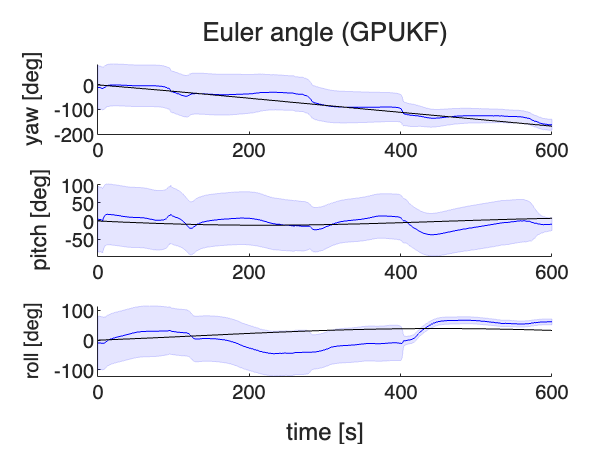

savedir = strcat(curdir, "/", dirName);

figname = "errorQuaternion";
figure('Name', strcat(figname), 'Visible','off');
tile = tiledlayout(4, 1);
nexttile
plot(t_, qe_gu(:,1), 'r');
yline(0, '-k');
xlim([0 t_(end,1)])
title(strcat('error quaternion (', filter, ')'));
nexttile;
plot(t_, qe_gu(:,2), 'g');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_gu(:, 3), 'b');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_gu(:, 4), 'm');
yline(0, '-k');
xlim([0 t_(end,1)])
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);


figname = "eulerAngle";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phi_gu_cov1 = rad2deg(phi_gu + 3.*sqrt(Pdiag_gu(:,1)));
phi_gu_cov2 = rad2deg(phi_gu - 3.*sqrt(Pdiag_gu(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phi_gu_cov1', fliplr(phi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(phi_gu), 'b');
hold on;
plot(t_, rad2deg(phi_true), 'k');
% hold on;
% plot(t_, rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1))), 'b--');
% hold on;
% plot(t_, rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1))), 'b--');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("yaw [deg]");

nexttile
theta_gu_cov1 = rad2deg(theta_gu + 3.*sqrt(Pdiag_gu(:,2)));
theta_gu_cov2 = rad2deg(theta_gu - 3.*sqrt(Pdiag_gu(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [theta_gu_cov1', fliplr(theta_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(theta_gu), 'b');
hold on;
plot(t_, rad2deg(theta_true), 'k');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("pitch [deg]");

nexttile
psi_gu_cov1 = rad2deg(psi_gu + 3.*sqrt(Pdiag_gu(:,3)));
psi_gu_cov2 = rad2deg(psi_gu - 3.*sqrt(Pdiag_gu(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psi_gu_cov1', fliplr(psi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(psi_gu), 'b');
hold on;
plot(t_, rad2deg(psi_true), 'k');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle (', filter, ')'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

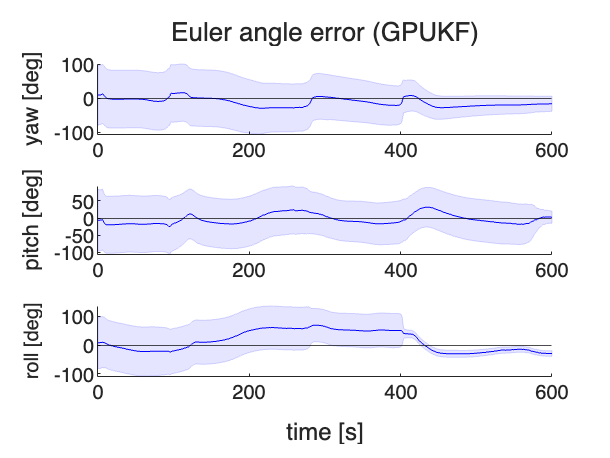



figname = "eulerAngleError";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phiE_gu_cov1 = rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1)));
phiE_gu_cov2 = rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phiE_gu_cov1', fliplr(phiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(phiE_gu), 'b');
% hold on;
% plot(t_, rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1))), 'b--');
% hold on;
% plot(t_, rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1))), 'b--');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("yaw [deg]");

nexttile
thetaE_gu_cov1 = rad2deg(thetaE_gu + 3.*sqrt(Pdiag_gu(:,2)));
thetaE_gu_cov2 = rad2deg(thetaE_gu - 3.*sqrt(Pdiag_gu(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [thetaE_gu_cov1', fliplr(thetaE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(thetaE_gu), 'b');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("pitch [deg]");

nexttile
psiE_gu_cov1 = rad2deg(psiE_gu + 3.*sqrt(Pdiag_gu(:,3)));
psiE_gu_cov2 = rad2deg(psiE_gu - 3.*sqrt(Pdiag_gu(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psiE_gu_cov1', fliplr(psiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(psiE_gu), 'b');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle error (', filter, ')'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

- UKF

% % UKF ------------
% filter = "UKF";
% dirName = strcat("../results/", resultDirName, "/", filter, "_staticFixed/"); % 絶対パスにすると，同じdirが2つできてしまうので
% mkdir(dirName);
% savedir = strcat(curdir, "/", dirName);
% 
% figname = "errorQuaternion";
% figure('Name', strcat(figname), 'Visible','off');
% tile = tiledlayout(4, 1);
% nexttile
% plot(t_, qe_u(:,1), 'r');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% title(strcat('error quaternion (', filter, ')'));
% nexttile;
% plot(t_, qe_u(:,2), 'g');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% nexttile;
% plot(t_, qe_u(:, 3), 'b');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% nexttile;
% plot(t_, qe_u(:, 4), 'm');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);
% 
% 
% figname = "eulerAngleError";
% figure('Name', figname);
% tile = tiledlayout(3,1, 'TileSpacing','Compact');
% nexttile
% phiE_u_cov1 = rad2deg(phiE_u + 3.*sqrt(Pdiag_u(:,1)));
% phiE_u_cov2 = rad2deg(phiE_u - 3.*sqrt(Pdiag_u(:,1)));
% p_u_cov = patch([t_', fliplr(t_')], [phiE_u_cov1', fliplr(phiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(phiE_u), 'r-'); 
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% % ylim([-30 30]);
% ylabel("yaw [deg]");
% 
% nexttile
% thetaE_u_cov1 = rad2deg(thetaE_u + 3.*sqrt(Pdiag_u(:,2)));
% thetaE_u_cov2 = rad2deg(thetaE_u - 3.*sqrt(Pdiag_u(:,2)));
% p_u_cov = patch([t_', fliplr(t_')], [thetaE_u_cov1', fliplr(thetaE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(thetaE_u), 'r');
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% % ylim([-30 30]);
% ylabel("pitch [deg]");
% 
% nexttile
% psiE_u_cov1 = rad2deg(psiE_u + 3.*sqrt(Pdiag_u(:,3)));
% psiE_u_cov2 = rad2deg(psiE_u - 3.*sqrt(Pdiag_u(:,3)));
% p_u_cov = patch([t_', fliplr(t_')], [psiE_u_cov1', fliplr(psiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(psiE_u), 'r');
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% % ylim([-30 30]);
% ylabel("roll [deg]", 'FontSize', 10);
% xlabel(tile, "time [s]")
% title(tile, strcat('Euler angle error (', filter, ')'));
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);

% UKF ------------
filter = "UKF";
dirName = strcat("../results/", resultDirName, "/", filter, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
mkdir(dirName);

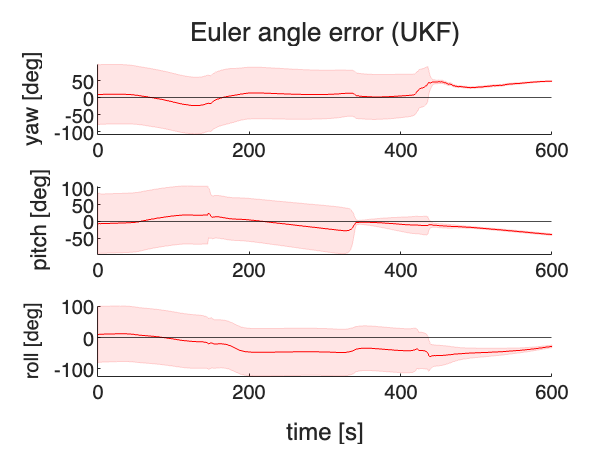

savedir = strcat(curdir, "/", dirName);

figname = "errorQuaternion";
figure('Name', strcat(figname), 'Visible','off');
tile = tiledlayout(4, 1);
nexttile
plot(t_, qe_u(:,1), 'r');
yline(0, '-k');
xlim([0 t_(end,1)])
title(strcat('error quaternion (', filter, ')'));
nexttile;
plot(t_, qe_u(:,2), 'g');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_u(:, 3), 'b');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_u(:, 4), 'm');
yline(0, '-k');
xlim([0 t_(end,1)])
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);


figname = "eulerAngleError";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phiE_u_cov1 = rad2deg(phiE_u + 3.*sqrt(Pdiag_u(:,1)));
phiE_u_cov2 = rad2deg(phiE_u - 3.*sqrt(Pdiag_u(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phiE_u_cov1', fliplr(phiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(phiE_u), 'r-'); 
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("yaw [deg]");

nexttile
thetaE_u_cov1 = rad2deg(thetaE_u + 3.*sqrt(Pdiag_u(:,2)));
thetaE_u_cov2 = rad2deg(thetaE_u - 3.*sqrt(Pdiag_u(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [thetaE_u_cov1', fliplr(thetaE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(thetaE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("pitch [deg]");

nexttile
psiE_u_cov1 = rad2deg(psiE_u + 3.*sqrt(Pdiag_u(:,3)));
psiE_u_cov2 = rad2deg(psiE_u - 3.*sqrt(Pdiag_u(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psiE_u_cov1', fliplr(psiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(psiE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle error (', filter, ')'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

- both of filters

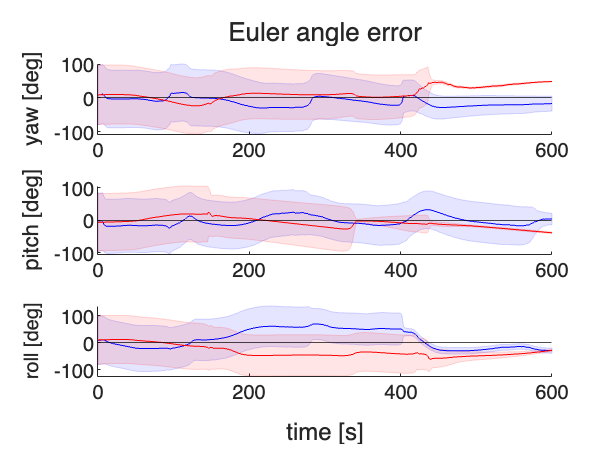

% % そのまま比較（not error）--------------
% dirName = strcat("../results/", resultDirName, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
% % mkdir(dirName);
% savedir = strcat(curdir, "/", dirName);
% 
% figname = "eulerAngle";
% figure('Name', figname);
% tile = tiledlayout(3,1, 'TileSpacing','Compact');
% nexttile
% phi_gu_cov1 = rad2deg(phi_gu + 3.*sqrt(Pdiag_gu(:,1)));
% phi_gu_cov2 = rad2deg(phi_gu - 3.*sqrt(Pdiag_gu(:,1)));
% phi_u_cov1 = rad2deg(phi_u + 3.*sqrt(Pdiag_u(:,1)));
% phi_u_cov2 = rad2deg(phi_u - 3.*sqrt(Pdiag_u(:,1)));
% p_u_cov = patch([t_', fliplr(t_')], [phi_u_cov1', fliplr(phi_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu_cov = patch([t_', fliplr(t_')], [phi_gu_cov1', fliplr(phi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu = plot(t_, rad2deg(phi_gu), 'b');
% hold on;
% p_u = plot(t_, rad2deg(phi_u), 'r');
% hold on;
% p_true = plot(t_, rad2deg(phi_true), 'k');
% hold on;
% % p_propagated = plot(t_, rad2deg(phi_propagated), 'g');
% hold off;
% % yline(0, '-k');
% xlim([0 t_(end,1)])
% ylabel("yaw [deg]");
% legend([p_gu, p_u, p_true], {'GPUKF', 'UKF', 'true value'})
% 
% nexttile
% theta_gu_cov1 = rad2deg(theta_gu + 3.*sqrt(Pdiag_gu(:,2)));
% theta_gu_cov2 = rad2deg(theta_gu - 3.*sqrt(Pdiag_gu(:,2)));
% theta_u_cov1 = rad2deg(theta_u + 3.*sqrt(Pdiag_u(:,2)));
% theta_u_cov2 = rad2deg(theta_u - 3.*sqrt(Pdiag_u(:,2)));
% p_u_cov = patch([t_', fliplr(t_')], [theta_u_cov1', fliplr(theta_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu_cov = patch([t_', fliplr(t_')], [theta_gu_cov1', fliplr(theta_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu = plot(t_, rad2deg(theta_gu), 'b');
% hold on;
% p_u = plot(t_, rad2deg(theta_u), 'r');
% hold on;
% p_true = plot(t_, rad2deg(theta_true), 'k');
% hold on;
% % p_propagated = plot(t_, rad2deg(theta_propagated), 'g');
% hold off;
% % yline(0, '-k');
% xlim([0 t_(end,1)])
% ylabel("pitch [deg]");
% 
% nexttile
% psi_gu_cov1 = rad2deg(psi_gu + 3.*sqrt(Pdiag_gu(:,3)));
% psi_gu_cov2 = rad2deg(psi_gu - 3.*sqrt(Pdiag_gu(:,3)));
% psi_u_cov1 = rad2deg(psi_u + 3.*sqrt(Pdiag_u(:,3)));
% psi_u_cov2 = rad2deg(psi_u - 3.*sqrt(Pdiag_u(:,3)));
% p_u_cov = patch([t_', fliplr(t_')], [psi_u_cov1', fliplr(psi_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu_cov = patch([t_', fliplr(t_')], [psi_gu_cov1', fliplr(psi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu = plot(t_, rad2deg(psi_gu), 'b');
% hold on;
% p_u = plot(t_, rad2deg(psi_u), 'r');
% hold on;
% p_true = plot(t_, rad2deg(psi_true), 'k-');
% hold on;
% % p_propagated = plot(t_, rad2deg(psi_propagated), 'g');
% hold off;
% % yline(0, '-k');
% xlim([0 t_(end,1)])
% ylabel("roll [deg]", 'FontSize', 10);
% xlabel(tile, "time [s]")
% title(tile, strcat('Euler angle'));
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);
% 
% % 観測モデルの回帰精度を可視化 ----------
% figname = "observationModelError";
% figure('Name', figname)
% % t = tiledlayout(2,1), nexttile
% p_gu = plot(t_, ye_gu, 'b'); 
% hold on;
% 
% p_lc_gpAtti = plot(t_, ye_lc_gpAtti, 'g');
% hold on;
% p_obs = plot(t_, mAppNoise, 'k-');
% hold on;
% p_obs.Color(4) = 0.5;
% 
% p_u = plot(t_, ye_u, 'r');
% 
% legendObj = legend([p_gu, p_lc_gpAtti, p_obs, p_u], {'GP model', 'Lc model(GPUKF)', 'Observed values', 'Lc model(UKF)'})
% title('Predicted and observed light curves [-]');
% xlim([0 t_(end,1)])%, ylim([-60 60])
% ylabel("light curve")
% set(gca, 'YDir', 'reverse')
% 
% % nexttile
% % plot(t_, yee_gu, 'g');
% % yline(0, '-k');
% % xlim([0 t_(end,1)])%, ylim([-60, 60]);
% % xlabel("time [s]");
% % ylabel("litht curve error between GP model and lc model")
% 
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);

% errorで比較
dirName = strcat("../results/", resultDirName, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
% mkdir(dirName);
savedir = strcat(curdir, "/", dirName);

figname = "eulerAngleError";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phiE_gu_cov1 = rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1)));
phiE_gu_cov2 = rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1)));
phiE_u_cov1 = rad2deg(phiE_u + 3.*sqrt(Pdiag_u(:,1)));
phiE_u_cov2 = rad2deg(phiE_u - 3.*sqrt(Pdiag_u(:,1)));
p_gu_cov = patch([t_', fliplr(t_')], [phiE_gu_cov1', fliplr(phiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_u_cov = patch([t_', fliplr(t_')], [phiE_u_cov1', fliplr(phiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(phiE_gu), 'b');
hold on;
plot(t_, rad2deg(phiE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("yaw [deg]");

nexttile
thetaE_gu_cov1 = rad2deg(thetaE_gu + 3.*sqrt(Pdiag_gu(:,2)));
thetaE_gu_cov2 = rad2deg(thetaE_gu - 3.*sqrt(Pdiag_gu(:,2)));
thetaE_u_cov1 = rad2deg(thetaE_u + 3.*sqrt(Pdiag_u(:,2)));
thetaE_u_cov2 = rad2deg(thetaE_u - 3.*sqrt(Pdiag_u(:,2)));
p_gu_cov = patch([t_', fliplr(t_')], [thetaE_gu_cov1', fliplr(thetaE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_u_cov = patch([t_', fliplr(t_')], [thetaE_u_cov1', fliplr(thetaE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(thetaE_gu), 'b');
hold on;
plot(t_, rad2deg(thetaE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("pitch [deg]");

nexttile
psiE_gu_cov1 = rad2deg(psiE_gu + 3.*sqrt(Pdiag_gu(:,3)));
psiE_gu_cov2 = rad2deg(psiE_gu - 3.*sqrt(Pdiag_gu(:,3)));
psiE_u_cov1 = rad2deg(psiE_u + 3.*sqrt(Pdiag_u(:,3)));
psiE_u_cov2 = rad2deg(psiE_u - 3.*sqrt(Pdiag_u(:,3)));
p_gu_cov = patch([t_', fliplr(t_')], [psiE_gu_cov1', fliplr(psiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_u_cov = patch([t_', fliplr(t_')], [psiE_u_cov1', fliplr(psiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(psiE_gu), 'b');
hold on;
plot(t_, rad2deg(psiE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle error'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);


phiE_u_normMean = mean(vecnorm(phiE_u))

phiE_u_normMean = 9.9656

thetaE_u_normMean = mean(vecnorm(thetaE_u))

thetaE_u_normMean = 7.2328

psiE_u_normMean = mean(vecnorm(psiE_u))

psiE_u_normMean = 16.3447


phiE_gu_normMean = mean(vecnorm(phiE_gu))

phiE_gu_normMean = 7.3926

thetaE_gu_normMean = mean(vecnorm(thetaE_gu))

thetaE_gu_normMean = 6.3171

psiE_gu_normMean = mean(vecnorm(psiE_gu))

psiE_gu_normMean = 16.1474

そのまま比較（not error）

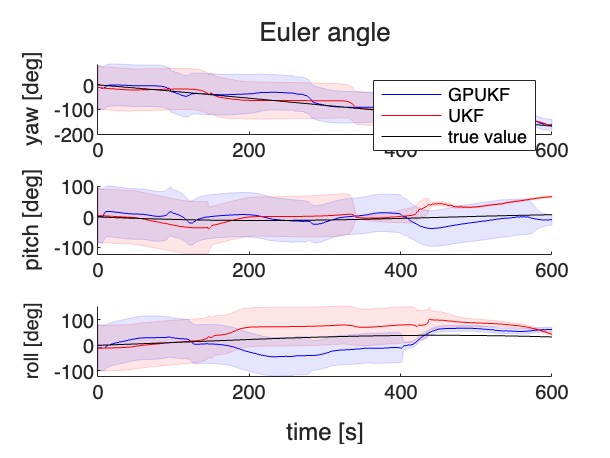

% そのまま比較（not error）--------------
dirName = strcat("../results/", resultDirName, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
% mkdir(dirName);
savedir = strcat(curdir, "/", dirName);

figname = "eulerAngle";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phi_gu_cov1 = rad2deg(phi_gu + 3.*sqrt(Pdiag_gu(:,1)));
phi_gu_cov2 = rad2deg(phi_gu - 3.*sqrt(Pdiag_gu(:,1)));
phi_u_cov1 = rad2deg(phi_u + 3.*sqrt(Pdiag_u(:,1)));
phi_u_cov2 = rad2deg(phi_u - 3.*sqrt(Pdiag_u(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phi_u_cov1', fliplr(phi_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu_cov = patch([t_', fliplr(t_')], [phi_gu_cov1', fliplr(phi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu = plot(t_, rad2deg(phi_gu), 'b');
hold on;
p_u = plot(t_, rad2deg(phi_u), 'r');
hold on;
p_true = plot(t_, rad2deg(phi_true), 'k');
hold on;
% p_propagated = plot(t_, rad2deg(phi_propagated), 'g');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)])
ylabel("yaw [deg]");
legend([p_gu, p_u, p_true], {'GPUKF', 'UKF', 'true value'})

nexttile
theta_gu_cov1 = rad2deg(theta_gu + 3.*sqrt(Pdiag_gu(:,2)));
theta_gu_cov2 = rad2deg(theta_gu - 3.*sqrt(Pdiag_gu(:,2)));
theta_u_cov1 = rad2deg(theta_u + 3.*sqrt(Pdiag_u(:,2)));
theta_u_cov2 = rad2deg(theta_u - 3.*sqrt(Pdiag_u(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [theta_u_cov1', fliplr(theta_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu_cov = patch([t_', fliplr(t_')], [theta_gu_cov1', fliplr(theta_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu = plot(t_, rad2deg(theta_gu), 'b');
hold on;
p_u = plot(t_, rad2deg(theta_u), 'r');
hold on;
p_true = plot(t_, rad2deg(theta_true), 'k');
hold on;
% p_propagated = plot(t_, rad2deg(theta_propagated), 'g');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)])
ylabel("pitch [deg]");

nexttile
psi_gu_cov1 = rad2deg(psi_gu + 3.*sqrt(Pdiag_gu(:,3)));
psi_gu_cov2 = rad2deg(psi_gu - 3.*sqrt(Pdiag_gu(:,3)));
psi_u_cov1 = rad2deg(psi_u + 3.*sqrt(Pdiag_u(:,3)));
psi_u_cov2 = rad2deg(psi_u - 3.*sqrt(Pdiag_u(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psi_u_cov1', fliplr(psi_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu_cov = patch([t_', fliplr(t_')], [psi_gu_cov1', fliplr(psi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu = plot(t_, rad2deg(psi_gu), 'b');
hold on;
p_u = plot(t_, rad2deg(psi_u), 'r');
hold on;
p_true = plot(t_, rad2deg(psi_true), 'k-');
hold on;
% p_propagated = plot(t_, rad2deg(psi_propagated), 'g');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)])
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

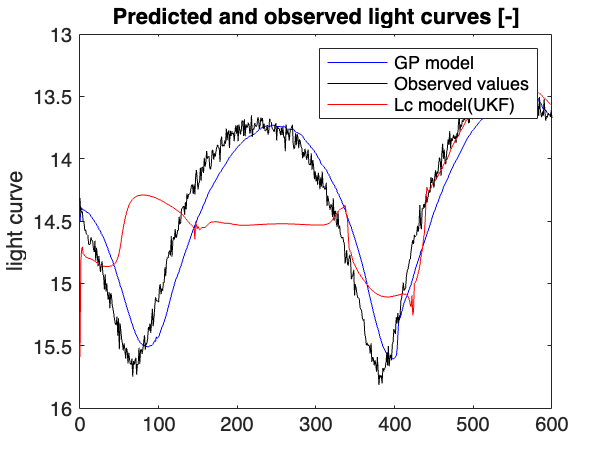


% 観測モデルの回帰精度を可視化 ----------
figname = "observationModelError";
figure('Name', figname)
% t = tiledlayout(2,1), nexttile
p_gu = plot(t_, ye_gu, 'b'); 
hold on;

% green line 消す for journal
% p_lc_gpAtti = plot(t_, ye_lc_gpAtti, 'g');
% hold on;
p_obs = plot(t_, mAppNoise, 'k-');
hold on;
p_obs.Color(4) = 0.5;

p_u = plot(t_, ye_u, 'r');

% legendObj = legend([p_gu, p_lc_gpAtti, p_obs, p_u], {'GP model', 'Lcmodel(GPUKF)', 'Observed values', 'Lc model(UKF)'});
legendObj = legend([p_gu, p_obs, p_u], {'GP model', 'Observed values', 'Lc model(UKF)'});
% legendObj = legend([p_gu, p_obs], {'GP model', 'Observed values'});
title('Predicted and observed light curves [-]');
xlim([0 t_(end,1)])%, ylim([-60 60])
ylabel("light curve")
set(gca, 'YDir', 'reverse')

% nexttile
% plot(t_, yee_gu, 'g');
% yline(0, '-k');
% xlim([0 t_(end,1)])%, ylim([-60, 60]);
% xlabel("time [s]");
% ylabel("litht curve error between GP model and lc model")

savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

tEnd = toc(tStart) / 60; % [min]
strcat("calculation time [min] : ", num2str(tEnd))

ans = "calculation time [min] : 6261.0013"

strcat("calculation time [hours] : ", num2str(tEnd/60))

ans = "calculation time [hours] : 104.35"